addpath('Kinematics')
addpath('Kinetics')
addpath('Control System')
addpath('Control System\Setpoint Control No FF')

supressed_print= evalc('run Linearize_EOMs.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

# Linear Moving Setpoint Controller

The feasibility of a setpoint controller for trajectory tracking is explored in this script. A traditional setpoint controller architecture is employed but the setpoint is not simple. The setpoint is chosen as the desired trajectory in x and y as functions of time. 

## Augmented System For State Space Representation of PID Controller

### Define State Vector With x Error States


$$\tilde{x}_{1a} = [
 \int_0^t \!e_x\, \mathrm{d}t ~ e_x ~ e_\dot{x} ~ \beta~\dot{\beta}]^T


$$



$$\dot{\tilde{x}}_{1a} = [
e_x ~e_\dot{x} ~ e_\ddot{x}  ~\beta~\dot{\beta}]^T$$


Where $e_\dot{x}$ is the error in the $x$ direction velocity,


$$e_\dot{x} = \dot{x}_s - \dot{x}$$


and $\(\int_{0}^{t} e_x \,\mathrm{d}t\)$ is the error in the integral of the $x$ position, 


$$ \int_0^t \!e_x\, \mathrm{d}t  ~=~  \int_0^t \!x_s\,   -  x\, \mathrm{d}t  ~=~  \int_0^t \!x_s\, \mathrm{d}t   ~-~ \int_0^t \!x\, \mathrm{d}t $$


stateVec1a = [e_ix, e_x, e_x_dot, beta, beta_dot].' %State vector augmented with integral of the error in x AND x and x_dot replaced with error states

$$stateVec1a = \left[\begin{array}{c} e_{\mathrm{ix}}\\ e_{x}\\ e_{\dot{x}}\\ \beta \\ \dot{\beta } \end{array}\right]$$

stateVec1a_dot = [e_x, e_x_dot, e_x_ddot, beta_dot, beta_ddot].'

$$stateVec1a\_dot = \left[\begin{array}{c} e_{x}\\ e_{\dot{x}}\\ e_{\ddot{x}}\\ \dot{\beta }\\ \ddot{\beta } \end{array}\right]$$

x_1a_dot_eqn = stateVec1a_dot == [e_x e_x_dot (x_ddot_s - x_ddot) beta_dot rhs(LIN_EOMS1(4))].'

$$x\_1a\_dot\_eqn = \left[\begin{array}{c} e_{x}=e_{x}\\ e_{\dot{x}}=e_{\dot{x}}\\ e_{\ddot{x}}=-\ddot{x}+{\ddot{x}}_{s}\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=112.8871\,x+64.8295\,\beta +383.5785\,T_{\beta } \end{array}\right]$$

x_1a_dot_eqn = stateVec1a_dot == subs(rhs(x_1a_dot_eqn), x_ddot , rhs(LIN_EOMS1(2)))

$$x\_1a\_dot\_eqn = \left[\begin{array}{c} e_{x}=e_{x}\\ e_{\dot{x}}=e_{\dot{x}}\\ e_{\ddot{x}}=5.2170\,x+{\ddot{x}}_{s}-4.0111\,\beta +17.7268\,T_{\beta }\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=112.8871\,x+64.8295\,\beta +383.5785\,T_{\beta } \end{array}\right]$$

x_1a_dot_eqn = subs(x_1a_dot_eqn, x, x_s - e_x)

$$x\_1a\_dot\_eqn = \left[\begin{array}{c} e_{x}=e_{x}\\ e_{\dot{x}}=e_{\dot{x}}\\ e_{\ddot{x}}=5.2170\,x_{s}+{\ddot{x}}_{s}-4.0111\,\beta -5.2170\,e_{x}+17.7268\,T_{\beta }\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=112.8871\,x_{s}+64.8295\,\beta -112.8871\,e_{x}+383.5785\,T_{\beta } \end{array}\right]$$

### Get Matrices for Error Dynamics


$$\dot{\tilde{x}}_{1a} = A_{1a}\tilde{x}_{1a} + B_{1a}T_\beta + S_{1a}\tilde{x}_{1s}$$


Where $S_{1a}$ is the input matrix for the setpoint vector $\tilde{x}_{1s} = [x_s ~\dot{x}_s~\ddot{x}_s]$. $A_{1e}$ is the state coupling matrix for the augmented - error state vector $\tilde{x}_{1a}$ and $B_{1a}$ is the input matrix for torque $T_\beta$. 

A1a = equationsToMatrix(rhs(x_1a_dot_eqn), stateVec1a)

$$A1a = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & -4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & -112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

B1a = equationsToMatrix(rhs(x_1a_dot_eqn), T_beta)

$$B1a = \left[\begin{array}{c} 0\\ 0\\ 17.7268\\ 0\\ 383.5785 \end{array}\right]$$


setpointVec1 = [x_s x_dot_s x_ddot_s].'

$$setpointVec1 = \left[\begin{array}{c} x_{s}\\ {\dot{x}}_{s}\\ {\ddot{x}}_{s} \end{array}\right]$$

S1a = equationsToMatrix(rhs(x_1a_dot_eqn), setpointVec1)

$$S1a = \left[\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 5.2170 & 0 & 1\\ 0 & 0 & 0\\ 112.8871 & 0 & 0 \end{array}\right]$$

## Create Data and Functions for Simulation (Moving Setpoint Controller)

A1a_sim = double(A1a);
B1a_sim = double(B1a);
S1a_sim = double(S1a);

Check controllability

rank(ctrb(A1a_sim, B1a_sim))

ans = 5

The system is fully controllable because the controllability matrix is full rank

%Our desired control output is the x state (want it to match as closely as possible to x_s
%for all times)

%x = x_s - e_x 
C1a_setp_ctrl = [0 -1 0 0 0]; 
D1a_setp_ctrl = [1 0 0];

### Moving Setpoint Parameters

r_sim = 50; % radius of circular trajectory [mm]
omega_sim =  2*pi/4; %angular frequency of circular trajectory 

des_traj_sym(t) = r_sim*sin(omega_sim*t);

### Overlay a fist order response so that the desired trajectory is smoothed out a bit

T = (2*pi/omega_sim)/5; %Time constant of the first order response that smooths out the trajectory
des_traj_sym(t) = (1 - exp(-(t/T)))*des_traj_sym;

### Find Integral and Derivatives of Trajectory

des_traj_sym_dot(t) = diff(des_traj_sym(t),t)

$$des\_traj\_sym\_dot(t) = 62.5000\,{\mathrm{e}}^{-1.2500\,t}\,\sin\left(1.5708\,t\right)-78.5398\,\cos\left(1.5708\,t\right)\,\left({\mathrm{e}}^{-1.2500\,t}-1\right)$$

des_traj_sym_ddot(t) = diff(des_traj_sym_dot(t),t)

$$des\_traj\_sym\_ddot(t) = 196.3495\,{\mathrm{e}}^{-1.2500\,t}\,\cos\left(1.5708\,t\right)-78.1250\,{\mathrm{e}}^{-1.2500\,t}\,\sin\left(1.5708\,t\right)+123.3701\,\sin\left(1.5708\,t\right)\,\left({\mathrm{e}}^{-1.2500\,t}-1\right)$$

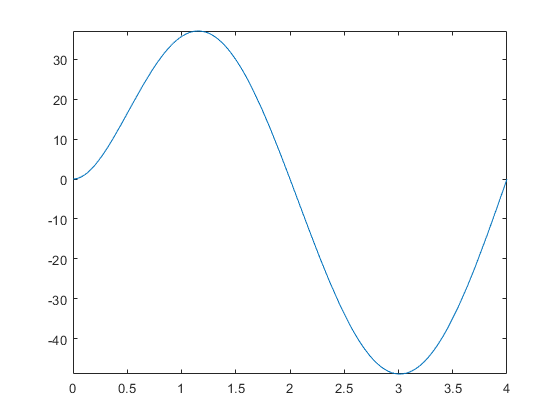

fplot(des_traj_sym) 
xlim([0 2*pi/omega_sim]);


%Create function handles from the desired trajectory information
des_traj_handle = matlabFunction([des_traj_sym;des_traj_sym_dot;des_traj_sym_ddot])

des_traj_handle = function_handle with value:
    @(t)[sin((t.*pi)./2.0).*(exp(t.*(-5.0./4.0))-1.0).*-5.0e+1;exp(t.*(-5.0./4.0)).*sin((t.*pi)./2.0).*(1.25e+2./2.0)-pi.*cos((t.*pi)./2.0).*(exp(t.*(-5.0./4.0))-1.0).*2.5e+1;exp(t.*(-5.0./4.0)).*sin((t.*pi)./2.0).*(-6.25e+2./8.0)+pi.^2.*sin((t.*pi)./2.0).*(exp(t.*(-5.0./4.0))-1.0).*(2.5e+1./2.0)+pi.*exp(t.*(-5.0./4.0)).*cos((t.*pi)./2.0).*(1.25e+2./2.0)]


## Place the poles of the closed loop transfer function 

This should have the effect of chossing PID gains such that the closed loop poles are in the left half plane. This provides for, at the very least, bounded input - bounded output stability. However, this tells us nothing directly about the tracking performance of the controller. 

### Place the poles of the closed loop transfer function 


$$\frac{{X_s}(s)}{X(s)}  = C_{1a}(SI - (A_{1a} - B_{1a}K_1))^{-1}S_{1a} + D_{1a}$$


where the matrices all belong to the augmented state space system. The effect is to avoid having to choose PID gains in an architecuture of the form


$$\frac{{X_s}(s)}{X(s)}  = \frac{C(s)P(s)}{1 + C(s)P(s)$$


where $C(s)$ is a PID controller and $P(s)$ is the open loop plant


$$P(s) = \frac{T_{\beta}(s)}{X(s)} = C_1(SI - A_1)^{-1}B_1$$
 

With the augmented system, we can simply use full state feedback to arbitrarily place the poles of the PID controller rather than having to use three dimensional root locus techniques in our choice of $K_i, ~K_p, ~and~K_d$. 

K1a = place(A1a_sim,B1a_sim, [-10 -20 -30 -4 -5]); 

## Simulate the Controller

%Specify simulation time
t_sim = 2*pi/omega_sim;
%Specify initial conditions
x1a_0 = [0 0 0 0 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system
%Select setpoint type
SP_sel = 1; %Sinusoidal input

out = sim('Linear_Moving_Setpoint_SS_PID')

out =   Simulink.SimulationOutput:

                   tout: [986x1 double] 
                    x1a: [986x5 double] 
                     y1: [986x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 
